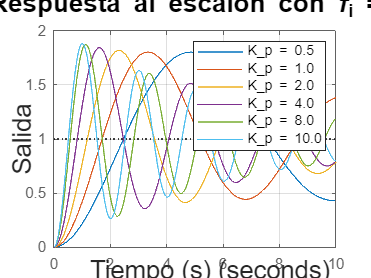

close all;
clear;
clc;

% Parámetros del sistema
K = 1;
p = 1;
t = 0:0.01:10;

%% Gráfica 1: tau_i fijo, Kp variable
taui_fixed = 1.5;
Kp_vals = [0.5, 1, 2, 4, 8, 10];

fig1 = figure('Units', 'centimeters', 'Position', [2, 2, 20, 15]);
hold on;
for i = 1:length(Kp_vals)
    Kp = Kp_vals(i);
    % Numerador y denominador de L(s)
    num_L = Kp * K * [taui_fixed, 1];
    den_L = conv([taui_fixed, 0], [1, p, 0]);  % taui*s * s*(s+p)
    
    % FT lazo cerrado H(s) = L(s)/(1 + L(s))
    L = tf(num_L, den_L);    % Lazo abierto
    sys = feedback(L, 1);    % Lazo cerrado: H(s) = L(s)/(1 + L(s))
    step(sys, t);
end
title(['Respuesta al escalón con \tau_i = ' num2str(taui_fixed)], 'FontSize', 17);
xlabel('Tiempo (s)', 'FontSize', 17);
ylabel('Salida', 'FontSize', 17);
legend(arrayfun(@(k) sprintf('K_p = %.1f', k), Kp_vals, 'UniformOutput', false));
grid on;
print(fig1, 'PI_salidaKpvar', '-dpdf', '-r300');

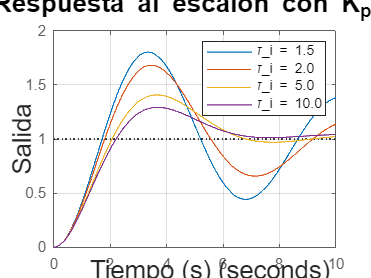


%% Gráfica 2: Kp fijo, tau_i variable
Kp_fixed = 1;
taui_vals = [1.5, 2, 5, 10];

fig2 = figure('Units', 'centimeters', 'Position', [2, 2, 20, 15]);
hold on;
for i = 1:length(taui_vals)
    taui = taui_vals(i);
    num_L = Kp_fixed * K * [taui, 1];
    den_L = conv([taui, 0], [1, p, 0]);  % taui*s * s*(s+p)
    
    L = tf(num_L, den_L);    % Lazo abierto
    sys = feedback(L, 1);    % Lazo cerrado: H(s) = L(s)/(1 + L(s))
    step(sys, t);
end
title(['Respuesta al escalón con K_p = ' num2str(Kp_fixed)], 'FontSize', 17);
xlabel('Tiempo (s)', 'FontSize', 17);
ylabel('Salida', 'FontSize', 17);
legend(arrayfun(@(t) sprintf('\\tau_i = %.1f', t), taui_vals, 'UniformOutput', false));
grid on;
print(fig2, 'PI_salidaTauivar', '-dpdf', '-r300');